% load configuration
close all
parameters;

%% find stiffness

theta = zeros(robot.theta_no,1);
 
N = robot.joint_no;
S1 = zeros(N, N);
S2 = zeros(N, 1);

iter = 30;   % nomber or experiments

robot.tool(1:3,4) = [0;0.1;0.1];

% experiments
for i = 1:iter
    % random force values
    force = zeros(6,1);
    force(1:3) = 2*rand(3,1)-1;    
    force = (force / norm(force)) * 1000;    
    % random joint values
    q0 = (pi/2)*(2*rand(robot.joint_no,1) - 1);    
    % displacement    
    [dt,dq] = delta_ee(q0,theta,force,robot);    
    % use only cartesian displacement
    dt = dt(1:3);
    A = get_A(q0, theta, force, robot);  
    
    % accumulate sum    
    S1 = S1 + A' * A;
    S2 = S2 + A' * dt;      
end

% results
ks = S1 \ S2;          % compliance

stiffness = 1 ./ ks  % stiffness

stiffness =    1.0e+06 *

    0.9657
    1.9260
    0.4951


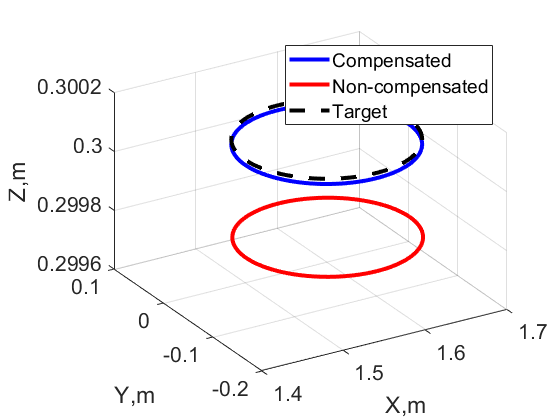


robot.tool = eye(4);

kq_backup = robot.Kq;

%% Trajectory

CONF = 5;
CONF2 = 7;
ZLVL = 0.3;
YLVL = 0;


m = configuration(CONF);
m2 = configuration(CONF2);

force = [-440;-1370;-635;0;0;0];

R = 0.1; 
X0 = 1.6;
Y0 = 0;

NP = 100;

alpha = linspace(0, 2*pi, NP);

JSh = zeros(3,NP);
JSv = zeros(3,NP);

XX = X0+R*cos(alpha);
YY = Y0+R*sin(alpha);

for i = 1:NP
    conf = IK([XX(i);YY(i);ZLVL;0;0;0], m, robot);
    %conf(4:6) = [0;0;0];
    JSh(:,i) = conf;
    
    conf = IK([XX(i);YLVL;YY(i);0;0;0], m2, robot);
    %conf(4:6) = [0;0;0];
    JSv(:,i) = conf;    
end

base = [XX',YY',ZLVL*ones(NP,1)];
% plot3(base(:,1),base(:,2),base(:,3));
% xlabel('X,m'); ylabel('Y,m'); zlabel('Z,m');
% figure;

%% Full model

circle1 = zeros(NP,3);
 
for i = 1:NP
    q = JSh(:,i);
    del = delta_ee(q, theta, force, robot);
    %circle1(i) = norm(del(1:3));
    circle1(i,:) = (del(1:3)+[XX(i);YY(i);ZLVL])';
end

% plot3(circle1(:,1),circle1(:,2),circle1(:,3), base(:,1),base(:,2),base(:,3));
% xlabel('X,m'); ylabel('Y,m'); zlabel('Z,m');

%% Reduced
robot.Kq = stiffness;
robot.use_links = false;

circle2 = zeros(NP,3);
 
for i = 1:NP
    q = JSh(:,i);
    del = delta_ee(q, theta, force, robot);
    %circle1(i) = norm(del(1:3));
    circle2(i,:) = (del(1:3)+[XX(i);YY(i);ZLVL])';
end

% figure;
% plot3(circle2(:,1),circle2(:,2),circle2(:,3));


%% New trajectory

diff = base - circle2;  % deflection
upd = base + diff;      % new 'initial' trajectory

robot.Kq = kq_backup;
robot.use_links = true;

circle4 = zeros(size(upd)); % after compensation
for i = 1:NP
    q = JSh(:,i);
    del = delta_ee(q,theta,force,robot);
    circle4(i,:) = del(1:3)' + upd(i,:);
end


figure
plot_circles([base(:,1), circle1(:,1), circle4(:,1)],[base(:,2), circle1(:,2), circle4(:,2)],[base(:,3), circle1(:,3), circle4(:,3)])

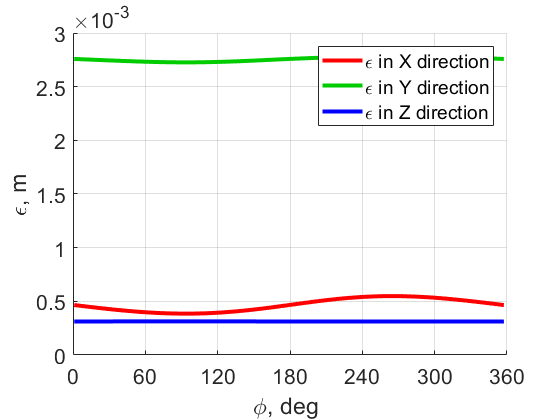





%% Compare

d3_full = base - circle1;
d3_comp = base - circle4;


show_err(1:360/size(d3_full,1):360,d3_full)

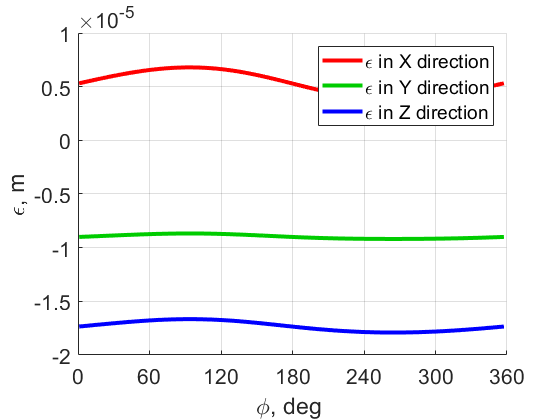



show_err(1:360/size(d3_comp,1):360,d3_comp)



disp_full = zeros(size(d3_full,1),1);
for i = 1:size(disp_full,1)
    disp_full(i) = norm(d3_full(i,:));
end

disp_comp = zeros(size(d3_comp,1),1);
for i = 1:size(disp_comp,1)
    disp_comp(i) = norm(d3_comp(i,:));
end

% figure;
% plot(disp_full);
% 
% figure;
% plot(disp_comp);
% figure
% plot_circles(circle2,disp_full,disp_comp)
